# 计算Ground Truth

## 导入观测数据

jIndex = {1 2 3 4 5 6 7 8 9 10 11};
[jLat, jLng, jFlag, jAlt] = jIndex{:};

FlagTable = sort(unique(data(:,jFlag)),'descend')

FlagTable = 5


% 0：无定位，1：单点定位，2：差分定位，4：RTK固定，收敛，5：RTK 浮点
if FlagTable(1) == 0
    error('No position')
else
    dataIndex = find(data(:,jFlag) == 4);
    if isempty(dataIndex)
        dataIndex = find(data(:,jFlag) == FlagTable(1));
    end
end
size(data,1)

ans = 410

size(dataIndex,1)

ans = 410

size(dataIndex,1)/size(data,1)

ans = 1

data = data(dataIndex,:);

AverData = mean(data,1);
LLADDD = [floor(AverData(jLat:jLng)/100)+mod(AverData(jLat:jLng),100)/60 AverData(jAlt)]

LLADDD =    30.5113  114.4012   54.2275



% Tag: 30.5111196984741	114.400952872416	55.5501552447553  1
% 30.5111525269941	114.401060902533	56.3913333333333 2
% 30.5111710221533	114.401131484398	52.4061173848440 2 673/777=0.8662
% 30.5114363803850	114.401163298368	68.0964522924411 2 807/807=1
% 30.5112909666485	114.401147486021	58.2640084033613 2 119/652=0.1825
% 30.5113049545911	114.401055406072	55.2210928381963 4 377/735=0.5129
% 30.5111640582291	114.401060404306	62.7457613997879 1 943/947=0.9958
% 30.5113162834679	114.401173782164	54.2275414634146 5 410/410=1


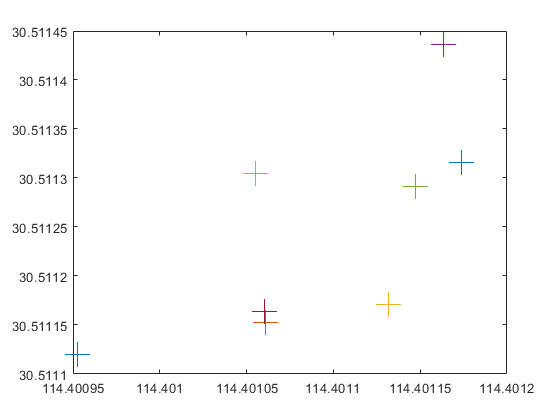

Position = [    30.5111196984741	114.400952872416	55.5501552447553;
                30.5111525269941	114.401060902533	56.3913333333333;
                30.5111710221533	114.401131484398	52.4061173848440;
                30.5114363803850	114.401163298368	68.0964522924411;
                30.5112909666485	114.401147486021	58.2640084033613;
                30.5113049545911	114.401055406072	55.2210928381963;
                30.5111640582291	114.401060404306	62.7457613997879;
                30.5113162834679	114.401173782164	54.2275414634146;];
p = [Position(:,2) Position(:,1)]';
figure
for i=1:size(p,2)
    plot(p(1,i),p(2,i),'+','MarkerSize',18)
hold on
end
hold off

% legend('tag','中1','东','南','北1','西','北2','中2')

% B
% A  C
iA = 1;iB = 2; iC = 3;
Altitude = 43.2;
Beacon = [
    30.511801,114.406786;
    30.511918,114.406791;
    30.511779,114.407003
];
Beacon = [Beacon ones(3,1)*Altitude]

Beacon =    30.5118  114.4068   43.2000
   30.5119  114.4068   43.2000
   30.5118  114.4070   43.2000


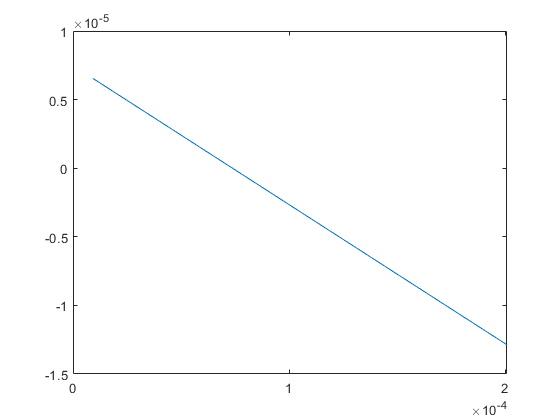


Wid = 16 + 2 * 0.5;
High = 10 + 2 * 0.5;

Nx = 7; Ny = 5;
Testpoint_x = (0.7:2.5:Wid); % 0.7 = 0.5 + 0.2
Testpoint_y = (0.7:2.5:High);

dx = (Beacon(iC, 1:2) - Beacon(iA, 1:2)) ./ Wid;
dy = (Beacon(iB, 1:2) - Beacon(iA, 1:2)) ./ High;

point_x = ones(Ny, Nx);
point_y = ones(Ny, Nx);

for j=1:Nx
    for i=1:Ny
        position = Testpoint_x(j) * dx + Testpoint_y(i) * dy;
        point_x(i,j) = position(2);
        point_y(i,j) = position(1);        
    end
end

figure
plot(point_x(1,:), point_y(1,:));

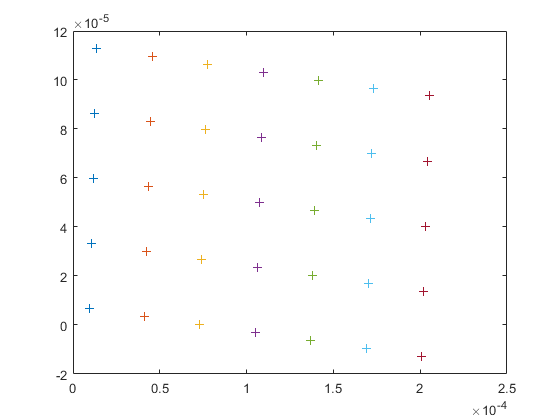

figure
plot(point_x, point_y,'+');


posx = Beacon(iA,2) + point_x;
posy = Beacon(iA,1) + point_y;

% pos
% x/y =
% 1   6   11 ...
% 2   7   12 ...
% 3   8   13 ...
% 4   9   14 ...
% 5   10  15 ...

% postionAll = [(1:Nx*Ny)'  posy(:) posx(:)];
postionAll = [(1:Nx*Ny)' posy(:) posx(:) ones(Nx*Ny, 1)*Altitude];
dlmwrite('groundTruth.txt',postionAll,'delimiter','\t','precision', 16,'newline','pc');



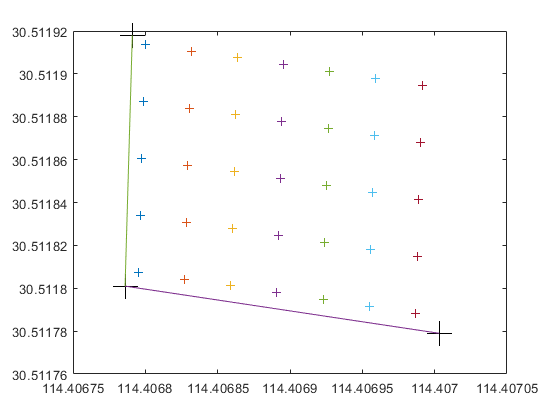

% figure
% plot(postionAll(:,2),postionAll(:,3),'+')
figure
plot(posx,posy,'+')
hold on
plot(Beacon(iA,2), Beacon(iA,1),'+k','MarkerSize',18);
hold on
plot(Beacon(iB,2), Beacon(iB,1),'+k','MarkerSize',18);
hold on
plot(Beacon(iC,2), Beacon(iC,1),'+k','MarkerSize',18);
hold on
plot(Beacon([iA iC],2), Beacon([iA iC],1))
hold on
plot(Beacon([iA iB],2), Beacon([iA iB],1))